1

Everything we do right now is in the frame of the first point that is detected. It is already assumed to be  (0,0,0).

m = 2

m = 2


r0 = 15 %Distance traversed

r0 = 15


k = -0.2

k = -0.2000

n = 10

n = 10

x_cam = -2

x_cam = -2

y_cam = -10

y_cam = -10

z_cam = -2

z_cam = -2

cam_cords = [x_cam, y_cam, z_cam]

cam_cords =     -2   -10    -2


% cam_cords is just (-(first point) coords in cam frame)


Plotting the ball path from between planes y= 0 and y = y_cam

syms t


xt(t) = t/m

$$xt(t) = \frac{t}{2}$$


yt(t) = t

$$yt(t) = t$$

rt(t) = sqrt(xt(t)^2+yt(t)^2)

$$rt(t) = \sqrt{\frac{5\,t^{2}}{4}}$$

zt(t) = k*rt(t)*(rt(t)-r0)

$$zt(t) = -\frac{\sqrt{\frac{5\,t^{2}}{4}}\,\left(\sqrt{\frac{5\,t^{2}}{4}}-15\right)}{5}$$


%kr(r-r0) = kr^2-kr0*r + 0
% a = k , b = -kr0, c = 0
a = k

a = -0.2000

b = -k*r0

b = 3

c = 0

c = 0


fplot3(xt-x_cam,yt-y_cam,zt-z_cam,[y_cam,0])

xlabel("x-axis")
ylabel("z-axis")
zlabel("y-axis")

Now we need to get a bunch of sample points, preferably in (x,y,z) format.

s = sort(y_cam*rand(1,n))

s =    -9.7059   -9.5949   -9.5717   -9.1574   -8.0028   -7.9221   -4.8538   -4.2176   -1.5761   -1.4189



fx = (double(xt(s)))-x_cam

fx =    -2.8530   -2.7975   -2.7858   -2.5787   -2.0014   -1.9610   -0.4269   -0.1088    1.2119    1.2906


fy = (double(yt(s)))-y_cam

fy =     0.2941    0.4051    0.4283    0.8426    1.9972    2.0779    5.1462    5.7824    8.4239    8.5811


fz = (double(zt(s)))-z_cam

fz =    11.0034   11.1667   11.2001   11.7504   12.8310   12.8816   12.3903   11.6992    6.6655    6.2557


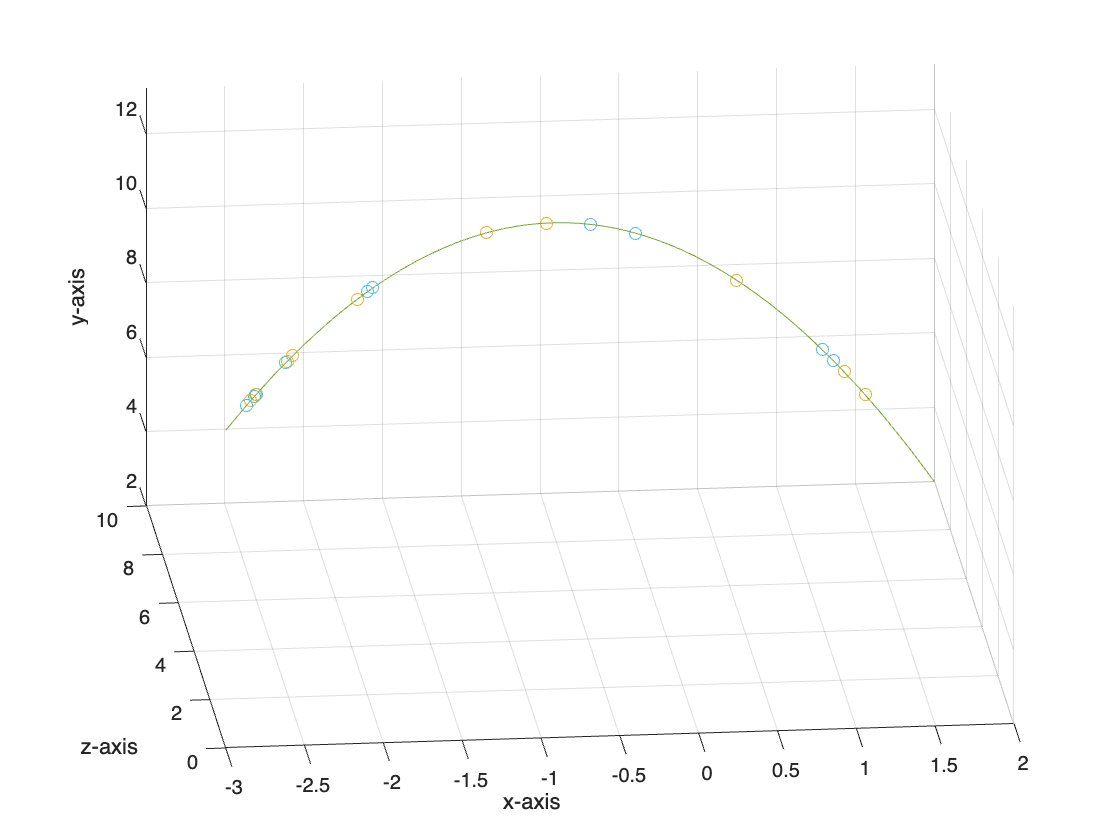



%Shift back to camera frame for final plot render
hold on
fplot3(xt-x_cam,yt-y_cam,zt-z_cam,[y_cam,0])
scatter3(fx,fy,fz)

class(fx)

ans = 'double'